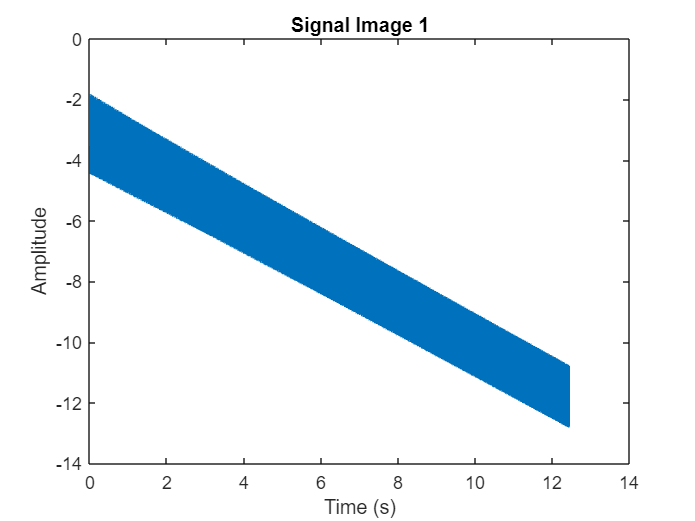

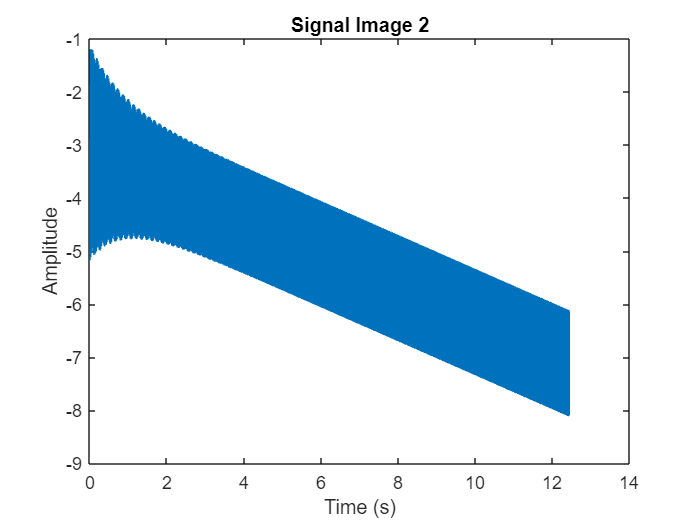

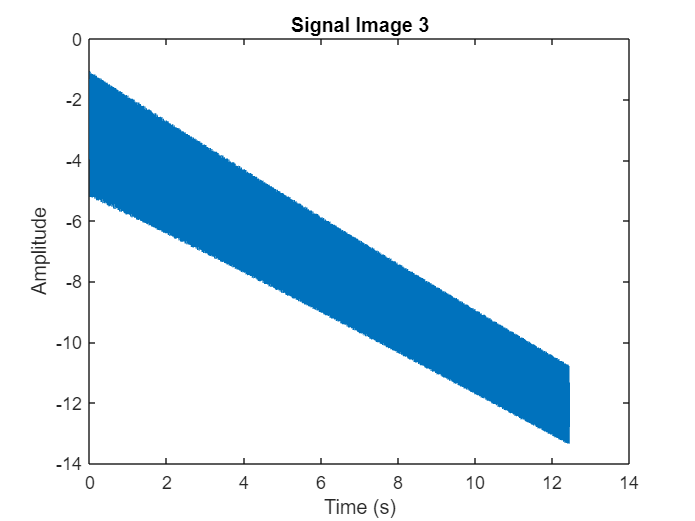

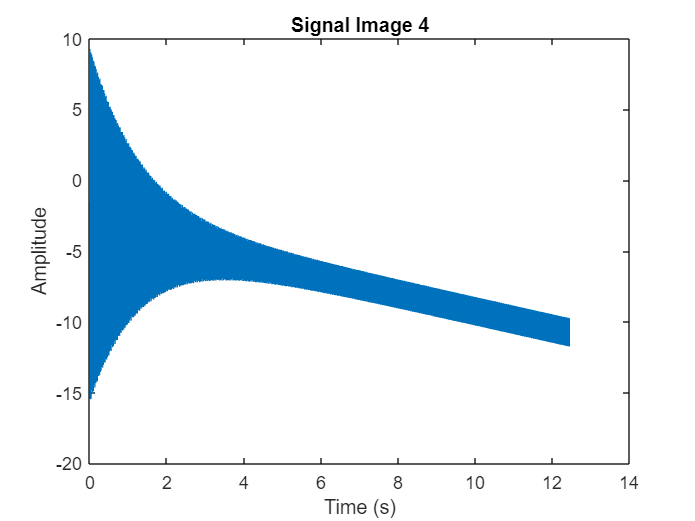

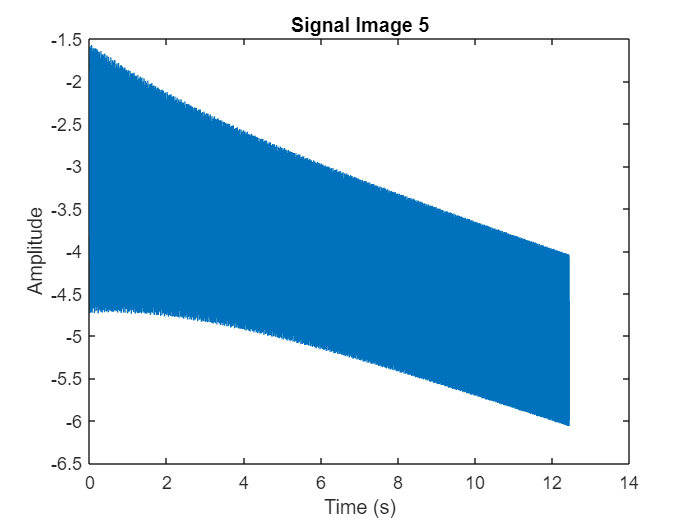

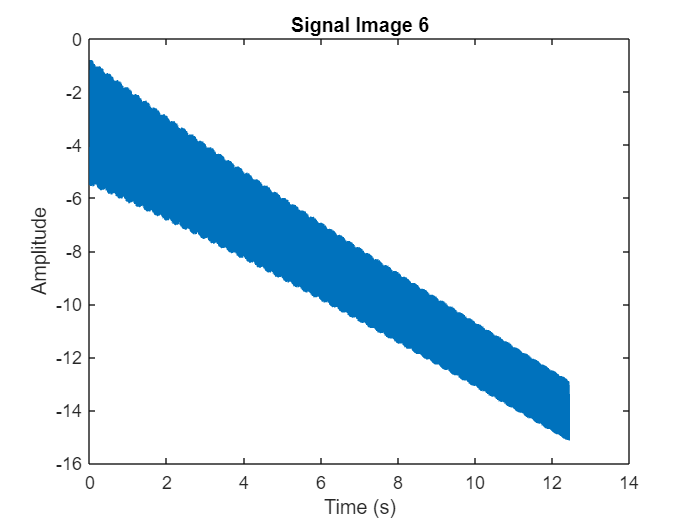

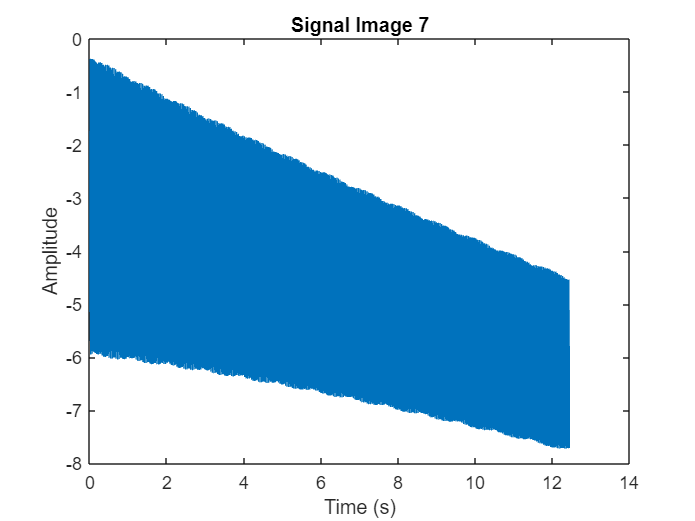

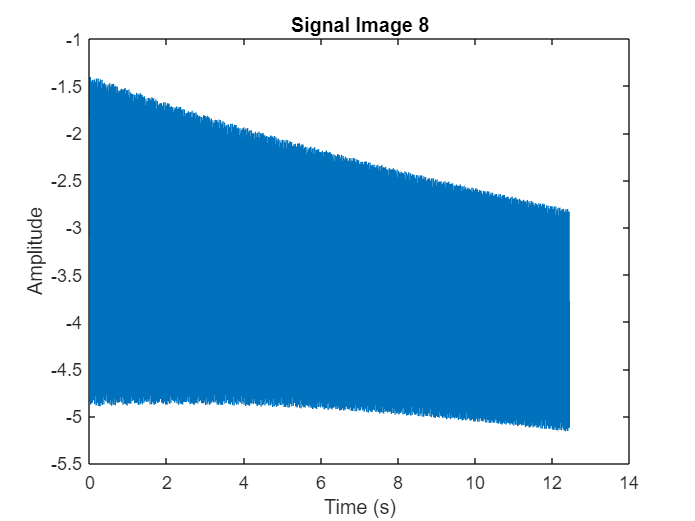

% Parameters
A = 1;                   % Amplitude
f = 50;                  % Frequency in Hz
sampling_rate = 3200;    % Sampling rate in Hz
num_cycles = 622;        % Number of cycles considered

% Time vector
T = 1 / f;                                      % Period of one cycle
duration = num_cycles * T;                      % Total duration of the signal
num_samples = duration * sampling_rate + 1;     % Number of samples
t = linspace(0, duration, num_samples);         % Time vector

% Angular frequency of the sinusoidal signal
omega = 2 * pi * f;
num_signals = 50;

% Generate 50 signal images
for signal_index = 1:num_signals
    % Define parameters
    beta = rand();          % Random beta in [0, 1]
    t1 = rand() * duration; % Random t1 within the duration of the signal
    tau = rand() * duration; % Random tau within the duration of the signal
    v = rand();             % Random v
    f = 300 + 600 * rand(); % Random frequency in [300, 900] Hz
    
    % Calculate the signal
    signal = A * ((sin(2 * pi * f * t - omega) - pi) - beta * exp(-(t - t1) / tau) .* sin(omega * (t - t1)) - v * t .* u(t));
    
    % Plot the signal
    figure;
    plot(t, signal);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Signal Image ', num2str(signal_index)]);
end